% Import the data, let's use the Puebla event to demonstrate
filename = 'C:\Users\mpontr01\Box\Data\Ground motion\Mexico CIty\Data\CE32\CE3220170919181440';
[fid3,~] = fopen(filename,'r');

Rosetta will now read all of the meta data from the RACM text file before going through any processing

fclose(fid3); % close the file

% now add necessary inputs. Rosetta pulls these from the 
% data file normally but for this demonstration, we'll simply
% input the values
fs = 100;

% OK, now let's read the ground motions, turn them into vectors,
% convert them to units of "g" and make a time vector
deliminator = '';
% Data starts in row 109, column 1
R = 109; % Row data start text file
C = 0; % column data start text file
data1 = dlmread(filename,deliminator,R,C); % retrieve data
NS = data1(:,1)/980; % North_South_Component
EW = data1(:,3)/980; % East_West_Component
V = data1(:,2)/980; % Vertical_Component
time = (1:length(V))/fs; % create a time vector

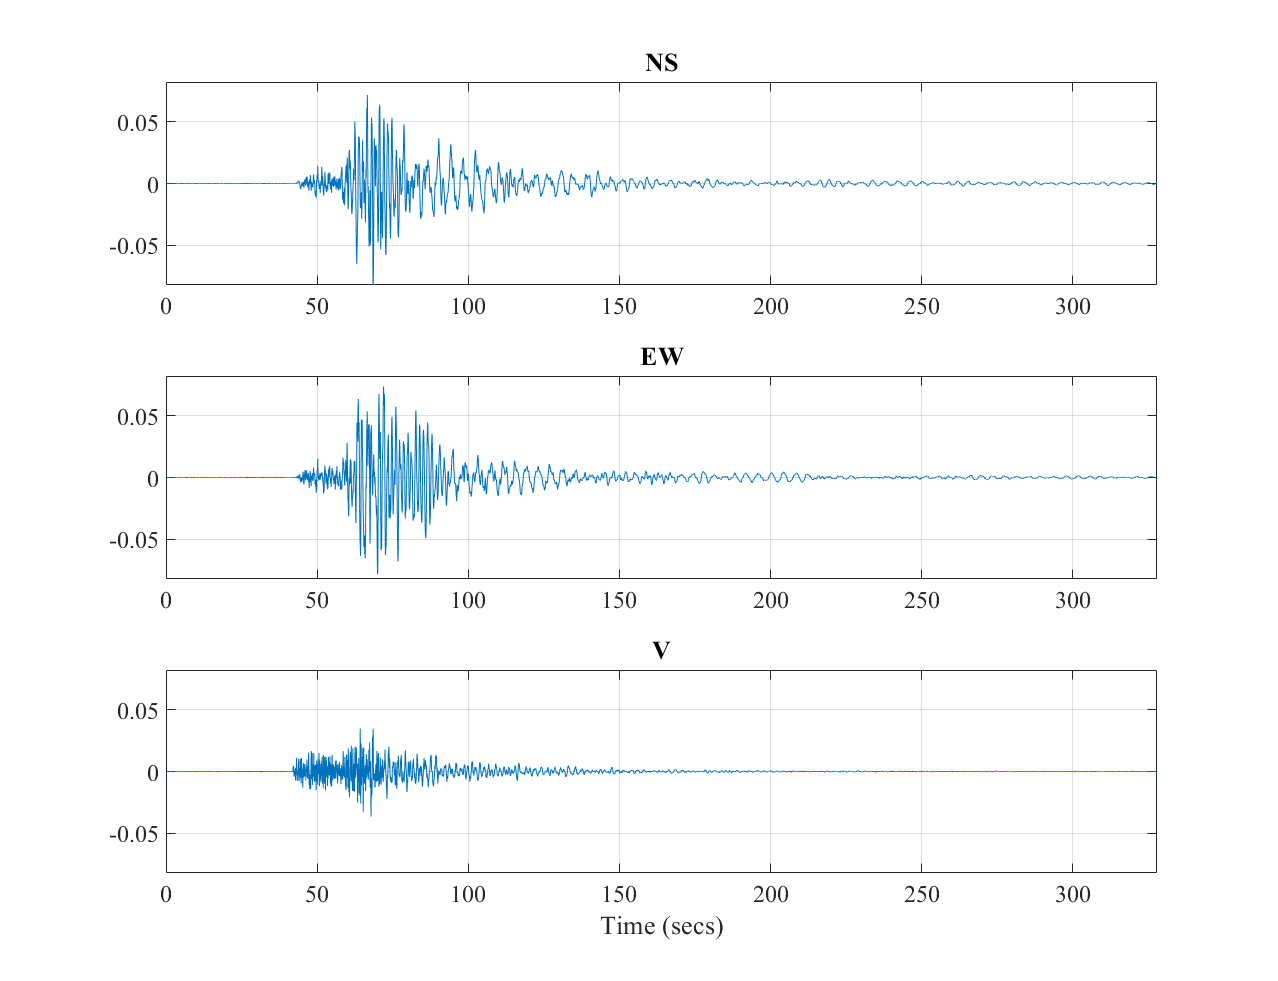

% Now let's plot the data
timeseriesplot(NS,EW, V, fs)

% This is a plot of the raw data, let's filter this using a 
% bandpass Butterworth filter
[NS, V, EW] = Butter(NS, V, EW, fs);

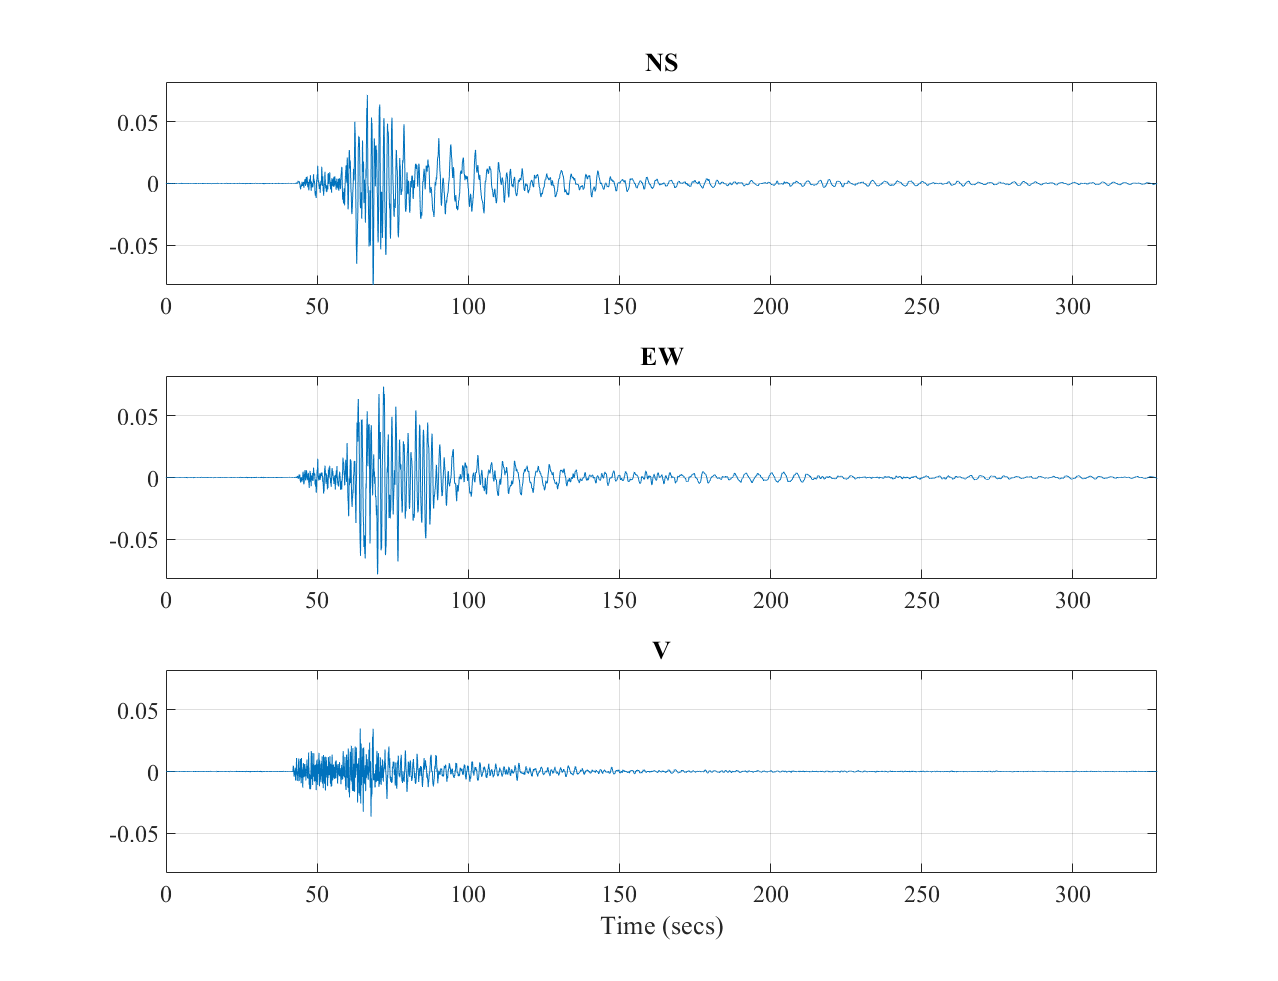

% Now let's plot the filtered data. This has almost no
% effect on these data, but will in other examples
timeseriesplot(NS,EW, V, fs)

% To ease in processing down the line, let's zero pad 
% record to 100,000 points. This piece of code counts
% how many points there are in the record, subtracts that
% number from 100,000 and adds the resulting number of
% zeros to each side of the record. If the number is an 
% odd number, the algorithm randomll chooses to add one
% more value to the beginning or the end of the record

% create the correct length vector of zeros
len = length(V);
f = (100000 - len)/2;
if mod(f,1) == 0
    c1 = zeros(1,f);
    c2 = zeros(1,f);
    loc1 = f;
    loc2 = 100000 - f;
else
    zz = randi([1, 2], 1);
    z = [0.5, -0.5];
    zzz = z(zz);
    q = (f + zzz);
    q1 = (f - zzz);
    c1 = zeros(1, q);
    c2 = zeros(1, q1);
    loc1 = q;
    loc2 = 100000 - q1;
end 

% Now zero pad the record
time = vertcat(c1',time',c2');
NS = vertcat(c1',NS,c2');
EW = vertcat(c1',EW,c2');
V = vertcat(c1',V,c2');

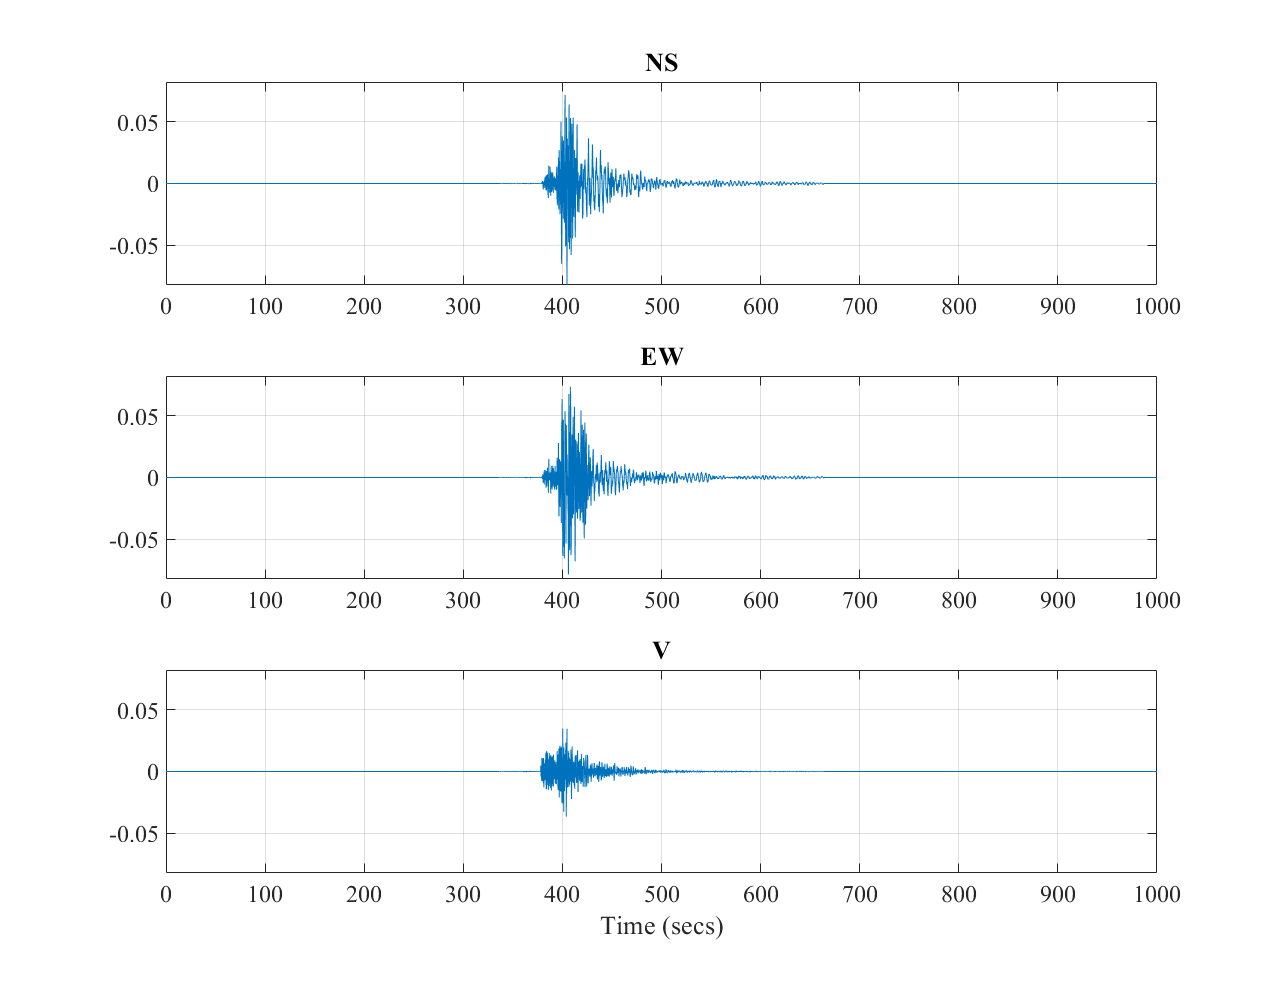

% Now let's plot the zero padded record 
timeseriesplot(NS,EW, V, fs)

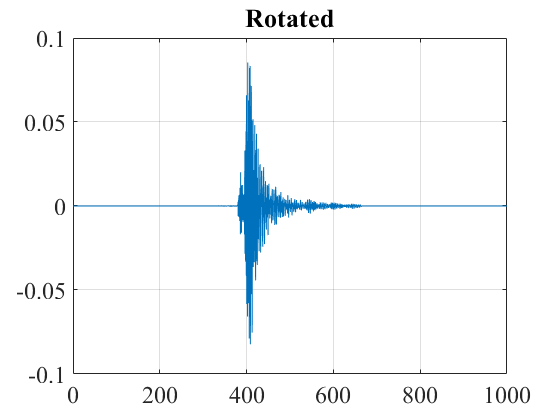

% Ok, so we've filtered the record, and zero padded it,
% the last thing we have to do is rotate it 45 degrees before we can get
% into integrating to velocity and displacement
for i = 1:length(NS)
    rot(i) = NS(i)*cos(pi/4) + EW(i)*sin(pi/4);
end
time = (1:length(rot))/fs;
figure
rot = rot';
plot(time,rot)
title('Rotated')
xlim([0 length(rot)/fs])
set(gca,'FontSize',20)
grid on 
box on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 18);

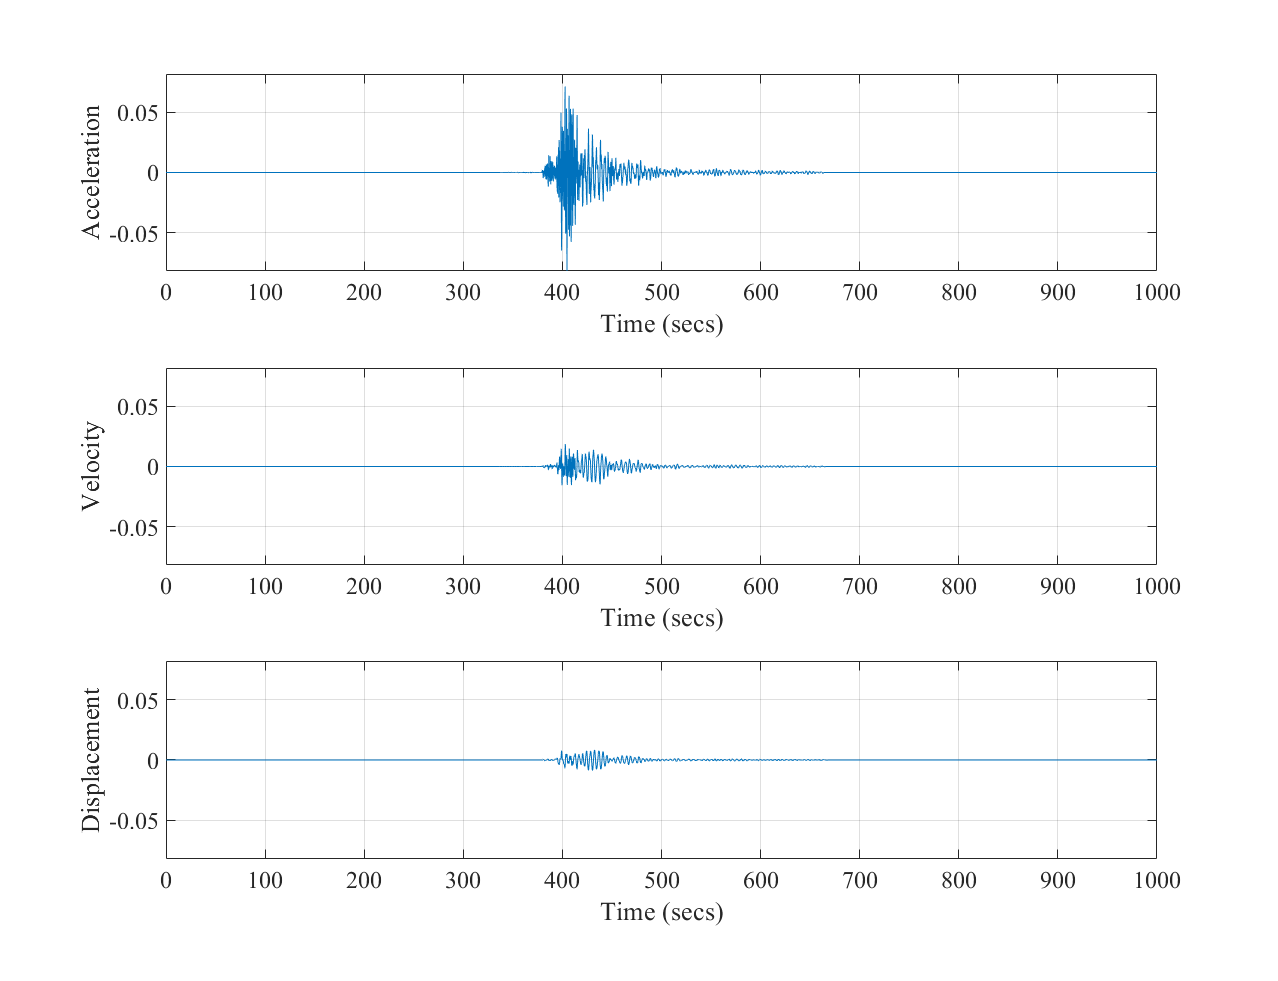

% Now let's integrate for velocity and displacement. We'll
% only demonstrate using the NS component, though this is
% done for all the components. We use the Newmark-Beta
% method of integration. 
[PGA1, PGV1, PGD1, v, d] =  waveform_integrate(NS, fs);
b = max(abs(NS));
figure

% acceleration
subplot(3,1,1)
plot(time, NS)
xlabel('Time (secs)')
ylabel('Acceleration')
ylim([-b b])
grid on 
box on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 18);

% velocity
subplot(3,1,2)
plot(time, v)
ylim([-b b])
xlabel('Time (secs)')
ylabel('Velocity')
grid on 
box on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 18);

% displacement
subplot(3,1,3)
plot(time, d)
ylim([-b b])
xlabel('Time (secs)')
ylabel('Displacement')
grid on 
box on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 18);
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

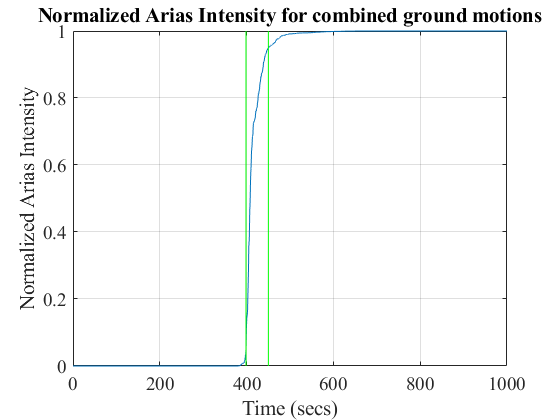

% Now let's calcualte the Arias intensity
[Iaval, D5D95, D5D75, rate_arias, Ianorm] =  Arias(time, NS, fs);
Arias_plot(time, Ianorm, D5D95, D5D75)